# MPS Discretization Tests

This live-script compares the solutions to the acoustic equations in 1D with MPS discretized by a staggered FD method.

Acoustic equations:


$$\frac{\partial p}{\partial t} + \kappa \frac{\partial v}{\partial x} = f(x,t)$$



$$\frac{\partial v}{\partial t} + \beta \frac{\partial p}{\partial x} = 0$$


Assumptions:

- 1D in space

- absorbing boundaries simulating unbounded domain

- zero initial conditions

- constant medium parameters

- single term multipole sources of the form $f(x,t) = w(t) \delta^{(s)}(x-x_*)$

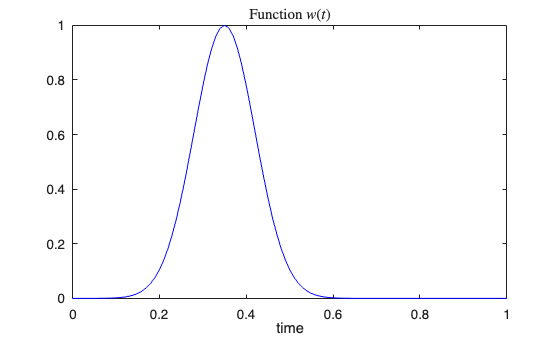


clear

domain_x = [0,2];
domain_t = [0,1];

% Setting up spatial grid
Nx=301;
grid_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_dual = Grid1DUnifDual(grid_primal);
gsp_P = GridSpace1D(grid_primal);
gsp_V = GridSpace1D(grid_dual);
dx = gsp_P.h;

% Acoustic medium parameters
medium = AcousticMedium1D.constant(BetaValue=4,KappaValue=1);
[kappa,beta,wspeed,cMax] = sampleMedium1D(gsp_P,medium);

% Setting up time grid
CFL_factor = 0.9;
dt = CFL_factor*(6/7)*dx/cMax;
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing to ensure time domain divisible by dt
t_pts = domain_t(1):dt:domain_t(2);

% Output spatial grid and time points
gsp_out   = GridSpace1D(Grid1DUnifPrimal(domain_x,201));
t_pts_out = linspace(domain_t(1),domain_t(2),101);

% Initial conditions
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

% Initializing PML
pml = PML1D(WidthLeft=0.2,WidthRight=0.2);

% Initialize solver
solver = AcousticSolver1D_PML( ...
    gsp_P,t_pts, ...
    gsp_out,t_pts_out, ...
    medium, pml, ...
    SpatialOrder=4);

% Common source parameters
x_src = 0.4;
tc = 0.35;
ts = 0.1;

appxOrder = 4;
tau = @(x,t) t-abs(x)/cMax;
w_src = @(t) exp(-((t-tc)/ts).^2);
dw_src = @(t) -2*(t-tc)/ts^2.*w_src(t);
ddw_src = @(t) -2*( w_src(t) + (t-tc).*dw_src(t) )/ts^2; 

% Plotting
figure;
plot(t_pts_out,w_src(t_pts_out),'-b');
xlabel("time")
title("Function $w(t)$",Interpreter="latex")

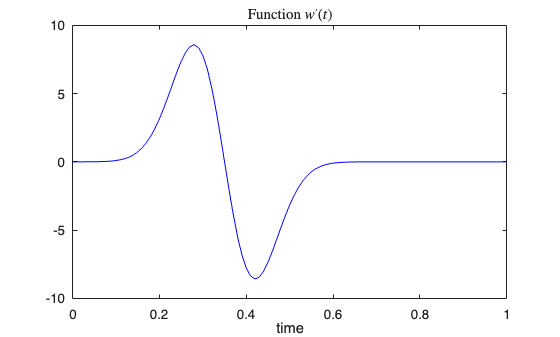

figure;
plot(t_pts_out,dw_src(t_pts_out),'-b');
xlabel("time")
title("Function $w'(t)$",Interpreter="latex");

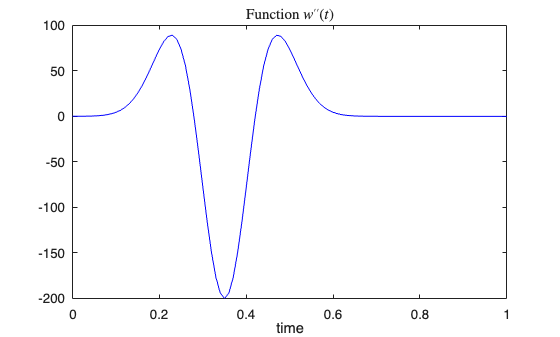


figure;
plot(t_pts_out,ddw_src(t_pts_out),'-b');
xlabel("time")
title("Function $w''(t)$",Interpreter="latex");

## Monopole Case

Source term: $f(x,t) = w(t) \delta(x-x_*)$

Analytical solution to the acoustic equations:


$$p(x,t) = \frac{1}{2c}w(\tau)$$


where $\tau = t - \frac{|x-x_*|}{c}$.

% Monopole source
delta_x = MultipoleComponent1D(x_src,0,TargetField="pressure");
monopole_term = MultipoleSrcTerm1D(delta_x,w_src);
monopole_src = monopole_term.discretize(gsp_P,gsp_V,appxOrder);

% Running solver
[P0,~] = solver.solve(p0,v0,Source=monopole_src);
norm(P0,Inf,Over="all")

ans = 0.2500


% True solution
monopole_soln = @(x,t) w_src(tau(x-x_src,t))/(2*cMax);
P0_true = GridFunctionTimeSeries(gsp_out,t_pts_out);
P0_true.setValues(monopole_soln);
P0_true.copyMetadataFrom(P0);

% Error
P0_err = P0_true-P0;
P0_err.label = "Pressure";
nrm2_err_t_0 = norm(P0_err,2,Over="time",Weighted=true);
nrm2_err_x_0 = norm(P0_err,2,Over="space",Weighted=true);
norm(P0_err,Inf,Over="all")

ans = 0.0011

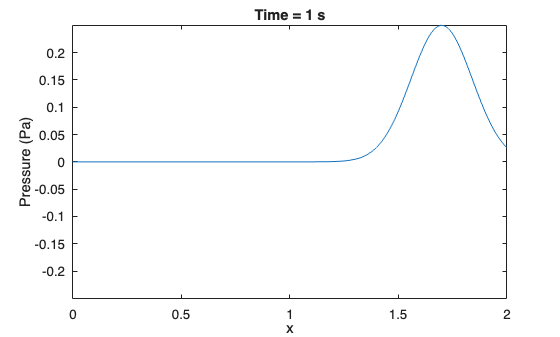

% Plots
P0.animate();

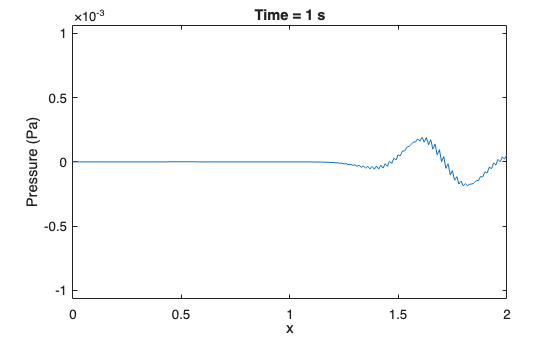

P0_err.animate();

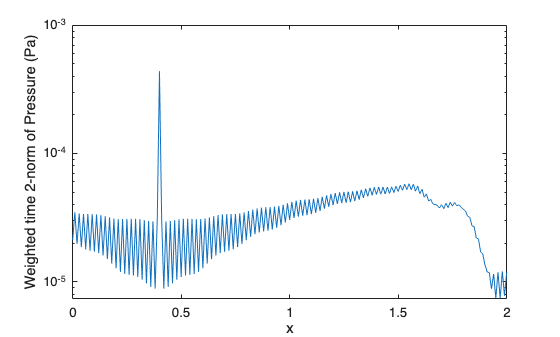

% Norm of error over time
h = nrm2_err_t_0.plot();
ax = ancestor(h,'axes');
ax.YScale = 'log';

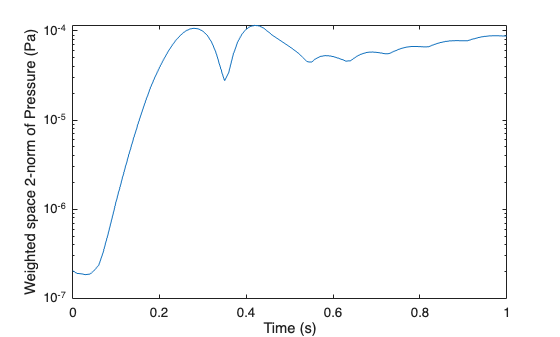

% Norm of error over space
h = nrm2_err_x_0.plotTimeSeries();
ax = ancestor(h,'axes');
ax.YScale = 'log';

## Dipole Case

Source term: $f(x,t) = w(t) \delta'(x-x_*)$

Analytical solution to the acoustic equations:


$$p(x,t) = -\frac{1}{2c^2}w'(\tau) \text{sign}(x-x_*)$$


where $\tau = t - \frac{|x-x_*|}{c}$.

% Dipole source
D1_delta_x = MultipoleComponent1D(x_src,1,TargetField="pressure");
dipole_term = MultipoleSrcTerm1D(D1_delta_x,w_src);
dipole_src = dipole_term.discretize(gsp_P,gsp_V,appxOrder);

% Running solver
[P1,~] = solver.solve(p0,v0,Source=dipole_src);
norm(P1,Inf,Over="all")

ans = 1.1079


% True solution
dipole_soln = @(x,t) -dw_src(tau(x-x_src,t))/(2*cMax^2).*sign(x-x_src);
P1_true = GridFunctionTimeSeries(gsp_out,t_pts_out);
P1_true.setValues(dipole_soln);
P1_true.copyMetadataFrom(P1);

% Error
P1_err = P1_true-P1;
P1_err.label = "Pressure";
nrm2_err_t_1= norm(P1_err,2,Over="time",Weighted=true);
nrm2_err_x_1 = norm(P1_err,2,Over="space",Weighted=true);
norm(P1_err,Inf,Over="all")

ans = 0.0395

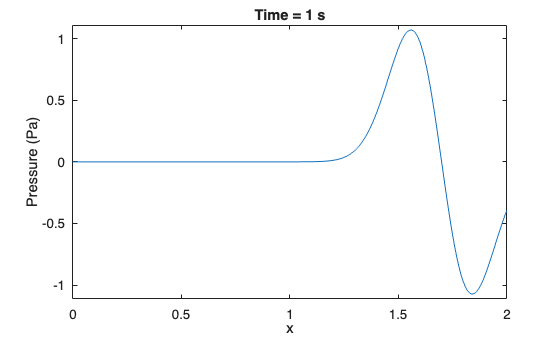

% Plots
P1.animate();

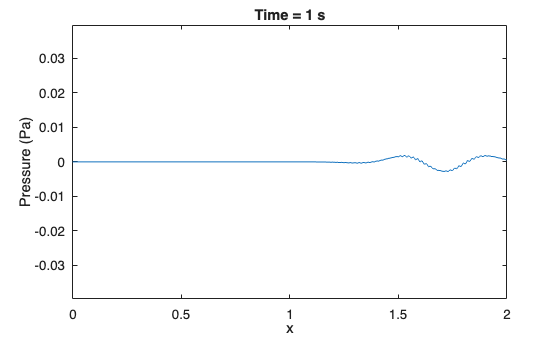

P1_err.animate();

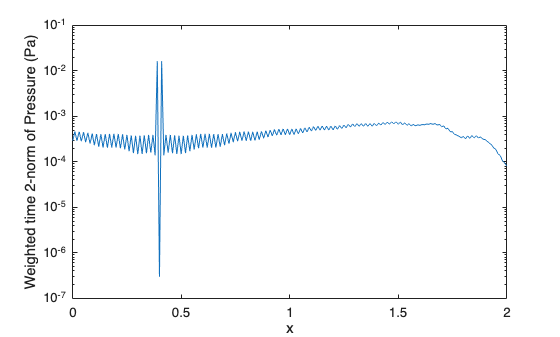

% Norm of error over time
h = nrm2_err_t_1.plot();
ax = ancestor(h,'axes');
ax.YScale = 'log';

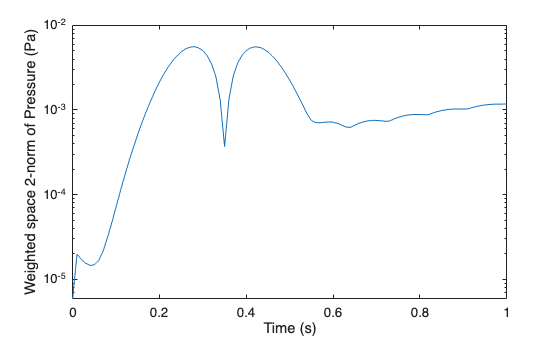

% Norm of error over space
h = nrm2_err_x_1.plotTimeSeries();
ax = ancestor(h,'axes');
ax.YScale = 'log';

## Quadrupole Case

Source term: $f(x,t) = w(t) \delta''(x-x_*)$

Analytical solution to the acoustic equations:


$$p(x,t) = \frac{1}{2c^3}w''(\tau) - \frac{1}{c^2}w'(\tau)\delta(x-x_*)$$


where $\tau = t - \frac{|x-x_*|}{c}$.

% Quadrupole source
D2_delta_x = MultipoleComponent1D(x_src,2,TargetField="pressure");
quadrupole_term = MultipoleSrcTerm1D(D2_delta_x,w_src);
quadrupole_src = quadrupole_term.discretize(gsp_P,gsp_V,appxOrder);

% Running solver
[P2,~] = solver.solve(p0,v0,Source=quadrupole_src);
norm(P2,Inf,Over="all")

ans = 319.0109


% True solution
quadrupole_soln = @(x,t) ddw_src(tau(x-x_src,t))/(2*cMax^3);
P2_true = GridFunctionTimeSeries(gsp_out,t_pts_out);
P2_true.setValues(quadrupole_soln);
P2_true.copyMetadataFrom(P2);

% Error
P2_err = P2_true-P2;
P2_err.label = "Pressure";
nrm2_err_t_2= norm(P2_err,2,Over="time",Weighted=true);
nrm2_err_x_2 = norm(P2_err,2,Over="space",Weighted=true);
norm(P2_err,Inf,Over="all")

ans = 318.8577

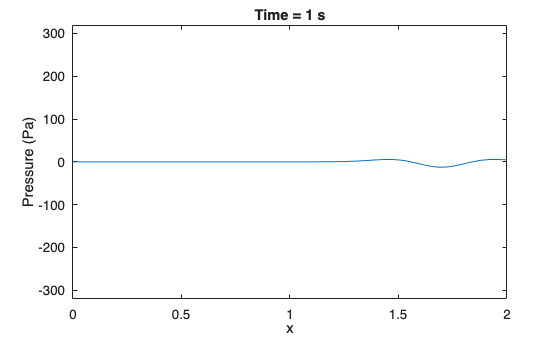

P2.animate();

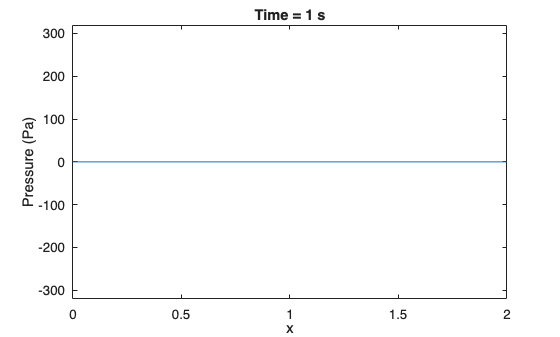

P2_err.animate();

% Norm of error over time
h = nrm2_err_t_1.plot();
ax = ancestor(h,'axes');
ax.YScale = 'log';

% Norm of error over space
h = nrm2_err_x_1.plotTimeSeries();
ax = ancestor(h,'axes');
ax.YScale = 'log';